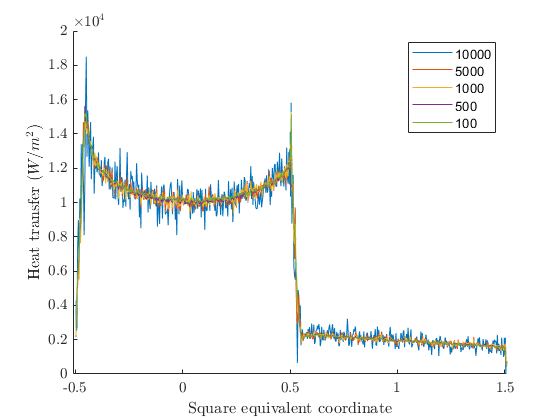

clear

D100=readmatrix('./timestep_average_convergence/surf100.20000.txt');
D100 = sortrows(D100(8:1279,1:10),1);

D500=readmatrix('./timestep_average_convergence/surf500.20000.txt');
D500 = sortrows(D500(8:1279,1:10),1);

D1000=readmatrix('./timestep_average_convergence/surf1000.20000.txt');
D1000 = sortrows(D1000(8:1279,1:10),1);

D5000=readmatrix('./timestep_average_convergence/surf5000.20000.txt');
D5000 = sortrows(D5000(8:1279,1:10),1);

D10000=readmatrix('./timestep_average_convergence/surf10000.20000.txt');
D10000 = sortrows(D10000(8:1279,1:10),1);

coords=coords('./timestep_average_convergence/squareroundhp.txt');
coords=coords(1:651,:);

fig1=figure;
hold on
plot(coords(1:651,2),D100(1:651,10))
plot(coords(1:651,2),D500(1:651,10))
plot(coords(1:651,2),D1000(1:651,10))
plot(coords(1:651,2),D5000(1:651,10))
plot(coords(1:651,2),D10000(1:651,10))
legend('10000','5000','1000','500','100')
xlabel('Equivalent square coordinate','interpreter','latex','FontSize',11)
ylabel('Heat transfer ($W / m^2$)','interpreter','latex','FontSize',11)
set(gca,'TickLabelInterpreter','latex','FontSize',11)
xlim([-0.51, 1.51])
ylim([0,2e4])
exportgraphics(fig1,'../Images/3. Methodology/Timestep average convergence/avesec.pdf','ContentType','vector');

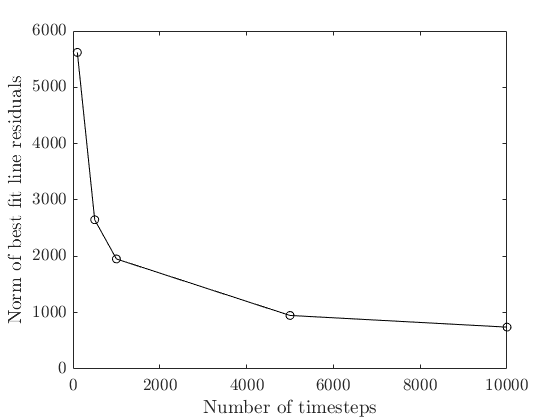



[p100, S100] = polyfit(D100(334:636,1),D100(334:636,10),1);
[p500, S500] = polyfit(D500(334:636,1),D500(334:636,10),1);
[p1000, S1000] = polyfit(D1000(334:636,1),D1000(334:636,10),1);
[p5000, S5000] = polyfit(D5000(334:636,1),D5000(334:636,10),1);
[p10000, S10000] = polyfit(D10000(334:636,1),D10000(334:636,10),1);

nts=[100,500,1000,5000,10000];
gof=[S100.normr,S500.normr,S1000.normr,S5000.normr,S10000.normr];

fig2=figure;
plot(nts,gof,'-ok')
xlabel('Number of timesteps','interpreter','latex','FontSize',13)
ylabel('Norm of best fit line residuals','interpreter','latex','FontSize',13)
set(gca,'TickLabelInterpreter','latex','FontSize',13)
exportgraphics(fig2,'../Images/3. Methodology/Timestep average convergence/rests.pdf','ContentType','vector');

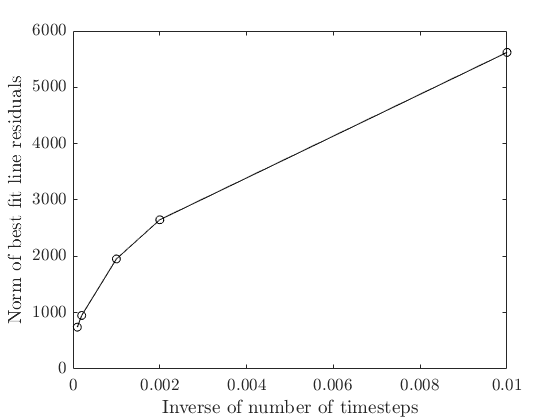


fig3=figure;
plot(1./nts,gof,'-ok')
xlabel('Inverse of number of timesteps','interpreter','latex','FontSize',13)
ylabel('Norm of best fit line residuals','interpreter','latex','FontSize',13)
set(gca,'TickLabelInterpreter','latex','FontSize',13)
exportgraphics(fig3,'../Images/3. Methodology/Timestep average convergence/resinvts.pdf','ContentType','vector');